clear;clc;close all;run('data.m');

# THERMAL SOLAR SYSTEM FOR DHW

## DATA

### Collector:

A = 2.14;                         % Effective absorber surface [m^2]
F_r = 64.2;                       % Flow rate [l/h]
M_r = F_r*1.035/3600;              % Mass rate [kg/s]
eta_0 = 0.802;                    % Efficency
U = 4.3;                          % [W/(m^2 K)]

### DHW circuit

L_c = 2.5;                        % Tank loss coefficient [W/K]
epsilon = 0.6;                    % Heat exchanger effectiveness
T_r = 18;                         % Room temperature (cellar) [°C]
T_in = 30;                        % Collector inlet temperature [°C]

### Dynamic model

N = 1;                            % Modules installed
V = 1.7;                          % Collector liquid content [L]
alpha = 0.95;                     % Collector absorption [-]

eta_zero = 0.802;                 % Optical efficiency at absorber [-]
a_1 = 4.28;                       % Coefficients of heat loss of the absorber [W/(m^2 K)]
a_2 = 0.0064;                     % Coefficients of heat loss of the absorber [W/(m^2 K^2)]
flow_rate = 64.2;                 % Recommended flow rate [L/h]
tank_loss_coeff = 2.5;            % Tank loss coefficient [W/(m^2 K)]
M_s = 200;                        % Tank content mass [kg]

c_joule = 4200;                   % Water specific heat capacity [J/(kg K)]
c = c_joule/60;                   % Water specific heat capacity [(W min)/(kg K)]

rho_w = 1;                        % Water density [kg/L] (assumed constant)
m_c = (flow_rate/60)*rho_w;         % Mass flow rate [kg/min]
T_home = 18;                      % Room temperature (cellar) [°C]

## 1 DISTRIBUTION

**Monthly and Yearly productivity of a fixed module. Conversion factor for direct radiation from a horizzontal surface to an inclined surface.**

### **Metereological input**

lat = 46.07;                      % Latitude [deg]
az = 0;                           % Panel azimuth [deg]
tilt = 30;                        % Tilt angle of the panel [deg]
rho_p = 0.2;                      % Substrate reflectance [-]

data;
I0 = 1367;                        % Energy falling on an extraterrestrial horizontal surface [W/m^2]
phi = pi/180*lat                  % Latitude [rad]

phi = 0.8041

gamma = az/180*pi;                % Azimith [rad]
beta = pi/180*tilt;               % Tilt [rad]
DT = Tmax - Tmin;               % Daily temperature variation

#### Solar Declination **(**$\delta$**)**:

 **Angle** between the **plane of the Earth's equator** and the **line connecting the Earth's center to the Sun's center, **$\delta = 23.45 \frac{\pi}{180}\sin\left(2\pi \frac{284+n}{365.25}\right) $.

delta = 23.45*pi/180*sin(2*pi*(284+n)/365.25); % Declination [rad]

#### Sunrise/Sunset angle ($\omega_s$):

**Angular distance** the Sun travels along the celestial equator from the observer's local celestial meridian (the line passing directly overhead, where solar noon occurs) until it reaches the horizon, $\omega_s = \arccos(-\tan(\phi)\tan(\delta))$.

omega_s = acos(-tan(phi)*tan(delta));          % Sunrise/Sunset angle on ground [rad]

#### Sunrise/Sunset time:

t_sr = -12/pi*omega_s + 12;        % Sunset time (h)
t_ss = 12/pi*omega_s + 12;         % Sunrise time (h)

## STATIC ANALYSIS

### Calculation of hourly irradiation values

$a\_$ and $b\_$ are two empirical factors used to calculate $r_t$, in order to **brake down** the Monthly Average Daily (MAD) irradiation into hourly values.

a_ = 0.409+0.5016*sin(omega_s-pi/3);
b_ = 0.6609-0.4767*sin(omega_s-pi/3);

Energy = zeros(12,1);
Power_Table = table();
t_max = 14;
Tin_0 = 30;

% Loop over 12 Months
for i=1:12
    time = linspace(t_sr(i), t_ss(i), 500)';
    omega = pi/12*(time-12); % Hour angle [rad]
    dt = time(2)-time(1);

            Hourly ambient temperature [°C]: $T_a = \frac{T_{max}(i) - T_{min}(i)}{2} + \frac{T_{max}(i) - T_{min}(i)}{2} \cdot \cos\left(\frac{2\pi}{24} \cdot (\text{time} - t_{\text{max}})\right)$

    Ta = (Tmax(i)+Tmin(i))/2 + (Tmax(i)-Tmin(i))/2*cos(2*pi/24*(time-tmax));
    

            Ratio of the hourly diffused irradiation to the daily total diffused irradiation: $r_{d} = \frac{\pi}{24} \cdot \frac{\cos\omega - \cos\omega_{s}}{\sin\omega_{s} - \omega_{s}\cos\omega_{s}}$, with $\omega$ = hour angle in the middle of each hour;

    rd = pi/24*(cos(omega)-cos(omega_s(i)))/(sin(omega_s(i))-omega_s(i)*cos(omega_s(i)));

            Ratio of the hourly total irradiation to the daily total irradiation: $r_{t} = \frac{\pi}{24}(a\_+b\_\cos\omega)\frac{\cos\omega - \cos\omega_{s}}{\sin\omega_{s} - \omega_{s}\cos\omega_{s}}$

    rt = rd.*(a_(i)+b_(i)*cos(omega));

            Transform the MAD energy values (from data.m -> D, H) into the energy incident on a horizontal plane ($MJ/m^2$) during the small time interval $dt$:

    Dt = rd*D(i)*dt/1;  % Diffuse Irradiation in a time interval dt [MJ/m^2] 
    Ht = rt*H(i)*dt/1;  % Total Irradiation in a time interval dt [MJ/m^2] 
    Bt = Ht - Dt;       % Beam Irradiation in a time interval dt [MJ/m^2] 

            Calculate the geometric relationship between the Sun and the surfaces for the precise instant defined by the hour angle $\omega
$.

    cosThetaz=cos(omega)*cos(delta(i))*cos(phi)+sin(delta(i))*sin(phi); % Cosine of the Zenith angle
    cosThetai = cos(beta)*(sin(delta(i))*sin(phi) + cos(delta(i))*cos(omega)*cos(phi)) - sin(beta)*(cos(gamma)*(cos(phi)*sin(delta(i)) - cos(delta(i))*cos(omega)*sin(phi)) - cos(delta(i))*sin(gamma)*sin(omega));
    % Cosine of the Angle of Incidence on the tilted plane

    Rt=cosThetai./cosThetaz; % Conversion factor for direct radiation from a horizontal surface to the inclined surface

            Combine the three energy components (Beam, Diffuse, Reflected) on the inclined surface, convert the energy rate back into power ($W/m^2
$), and correct for non-physical

            results. With $Hbt = \left(B_t \cdot R_t + D_t \cdot \left(\frac{1+\cos\beta}{2}\right) + \left(\frac{1-\cos\beta}{2}\right)\rho_p \cdot H_t\right) \cdot \frac{10^6}{3600 \cdot dt}$.

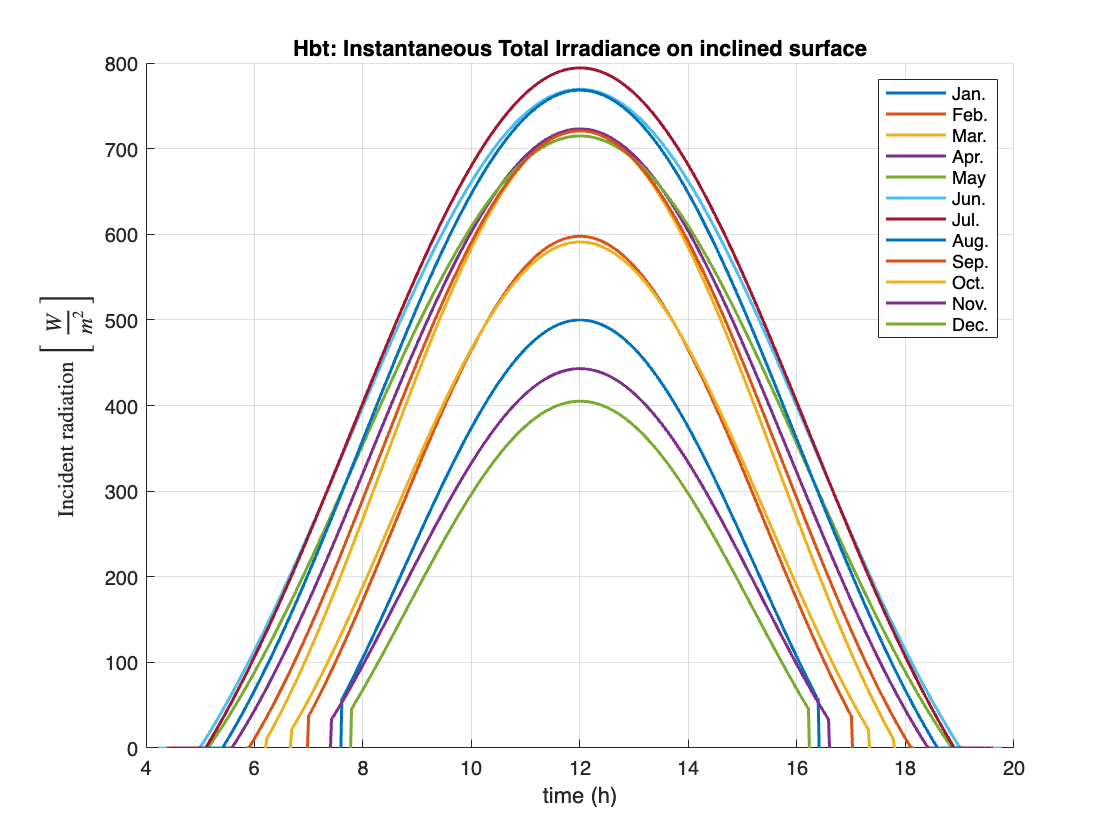

    Hbt = (Bt.*Rt+Dt.*((1+cos(beta))/2)+((1-cos(beta))/2)*rho_p.*Ht)*1e6/(3600*dt); % Radiation (instantaneous power) [W/m^2] 
    Hbt(1) = 0; Hbt(end) = 0; 
    Hbt(Hbt<0) = 0;

    eta = eta_0-U*(Tin_0-Ta)./Hbt; % Collector efficiency factor
    eta(eta<0) = 0; eta(isnan(eta)) = 0;

    Power_inst = (Hbt.*eta)*A;

    % Build tables
    t_sr_Table.Month = t_sr;
    t_ss_Table.Month = t_ss;
    I_Table.Month{i} = Hbt;
    Ta_Table.Month{i} = Ta;
    Eta_Table.Month{i} = eta;
    Power_Table.Month{i} = Power_inst;

    Ht_Table.Month{i} = Ht;
    Bt_Table.Month{i} = Bt;
    Dt_Table.Month{i} = Dt;

    % Plot figures
    fig = 1;
    % Hbt: Instantaneous Total Irradiance
    figure(fig)
    hold on 
    plot(time,Hbt,'LineWidth',1.5)
    
    % Ta: Hourly ambient temperature
    fig = fig+1;
    figure(fig)
    hold on
    plot(time,Ta,'LineWidth',1.5)

    % eta: Collector efficiency factor
    fig = fig+1;
    figure(fig)
    hold on
    plot(time,eta,'LineWidth',1.5)

    % Instantaneous power
    fig = fig+1;
    figure(fig)
    hold on
    plot(time,Power_inst,'LineWidth',1.5)   
end    
% Hbt: Instantaneous Total Irradiance on inclined surface
figure(1)
grid on
xlabel('time (h)')
ylabel('Incident radiation $\left[\;\frac{W}{m^2}\;\right]$','Interpreter','latex');
legend('Jan.','Feb.','Mar.','Apr.','May','Jun.','Jul.','Aug.','Sep.','Oct.','Nov.','Dec.')
title('Hbt: Instantaneous Total Irradiance on inclined surface');

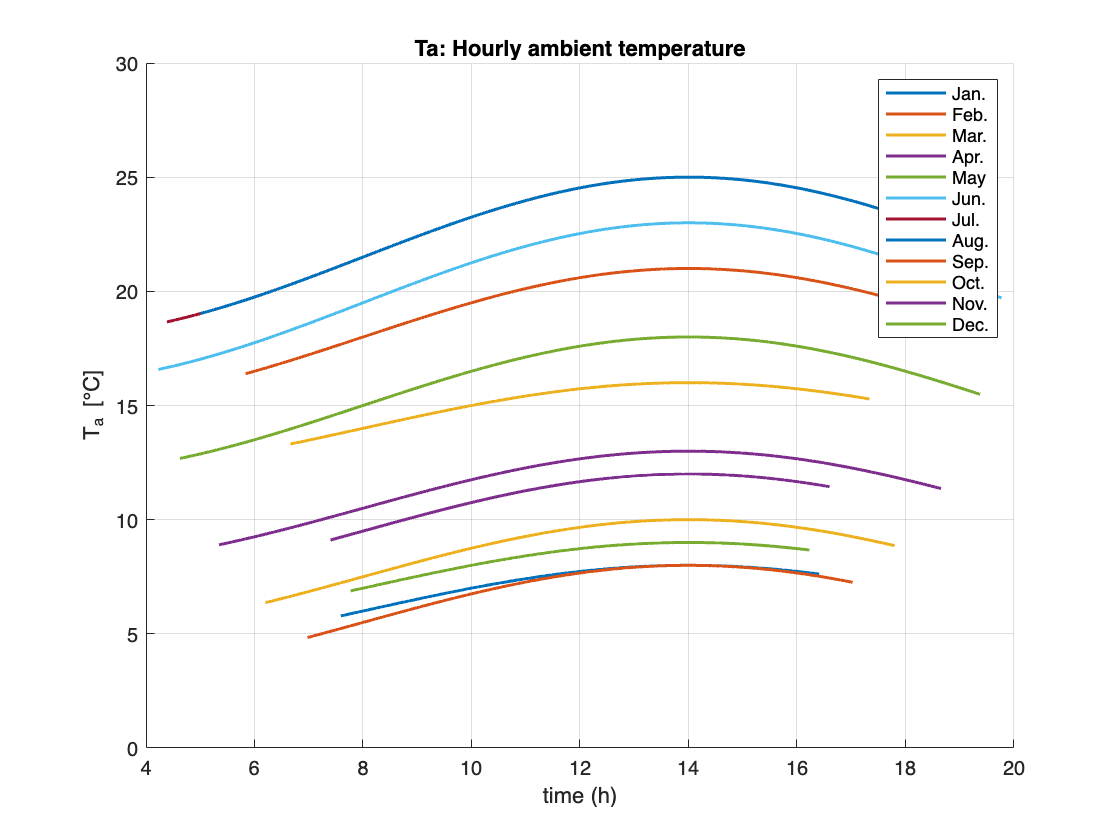

% Ta: Hourly ambient temperature
figure(2)
grid on
xlabel('time (h)')
ylabel('T_a [°C]');
legend('Jan.','Feb.','Mar.','Apr.','May','Jun.','Jul.','Aug.','Sep.','Oct.','Nov.','Dec.')
ylim([0 30])
title('Ta: Hourly ambient temperature');

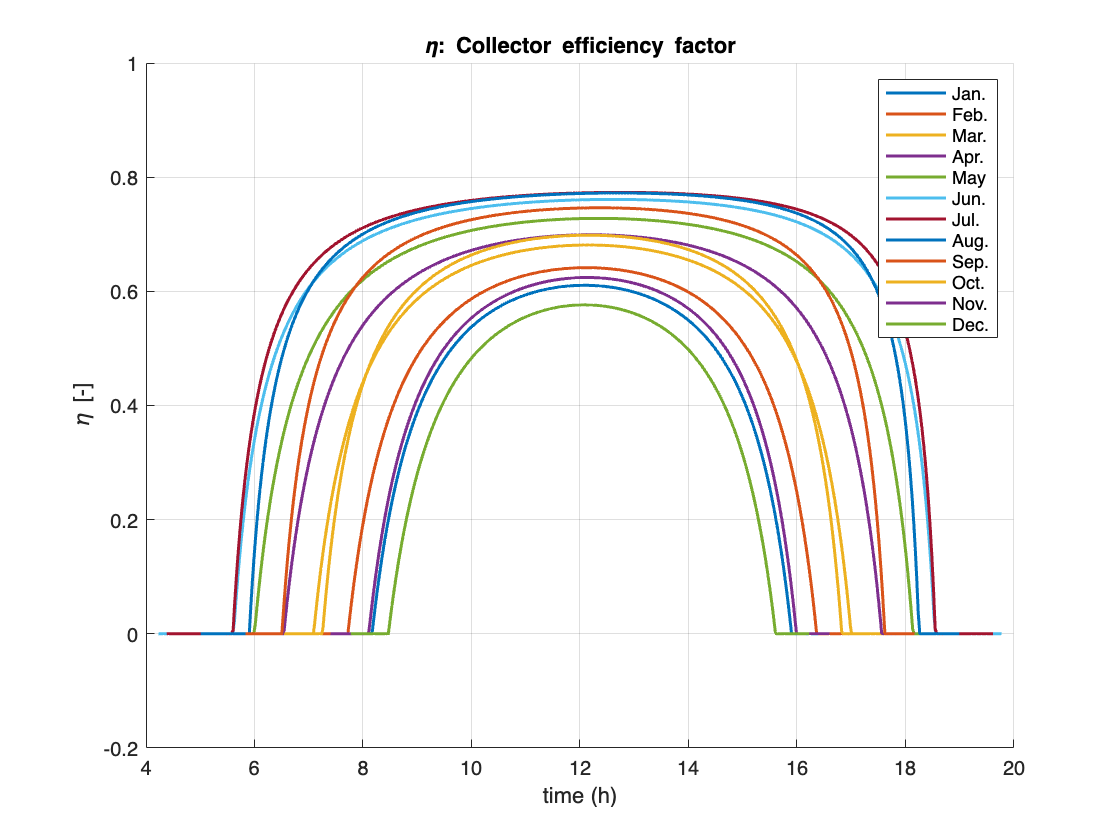

% eta: Collector efficiency factor
figure(3)
grid on
xlabel('time (h)')
ylabel('\eta [-]')
legend('Jan.','Feb.','Mar.','Apr.','May','Jun.','Jul.','Aug.','Sep.','Oct.','Nov.','Dec.')
ylim([-0.2 1])
title('\eta: Collector efficiency factor');

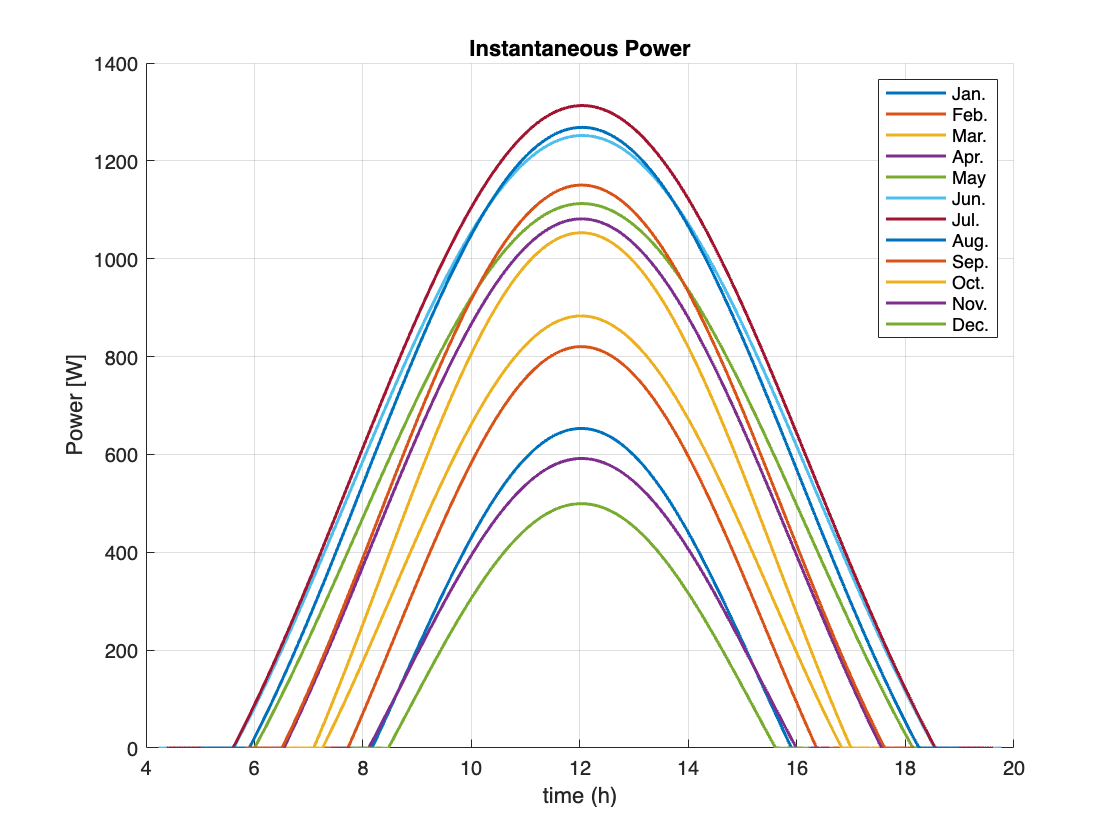

% Instantaneous power
figure(4)
grid on
xlabel('time (h)')
ylabel('Power [W]')
legend('Jan.','Feb.','Mar.','Apr.','May','Jun.','Jul.','Aug.','Sep.','Oct.','Nov.','Dec.')
hold off;
title('Instantaneous Power');

### Annual Thermal Energy yield of the collector

Annual_TE = 0;
day_length = t_ss-t_sr;

% Loop over 12 Months
for i = 1:12
    delta_t = day_length(i)/500;                  % Time step of the average day of the i-th month
    Daily_TE = sum(Power_Table.Month{i}*delta_t); % Average daily thermal energy of the i-th month
    Monthly_TE = Daily_TE*Month_day(i);           % Average monthly thermal energy of the i-th month
    Annual_TE = Annual_TE + Monthly_TE;           % Adding on the annual thermal energy the contributions of every month
end
disp(['Annual thermal energy yeld of the collector: ',num2str(Annual_TE/1000),' [KWh]'])

Annual thermal energy yeld of the collector: 2300.0463 [KWh]


## DYNAMIC ANALYSIS

Focus on the dynamic behaviour of the system in a couple of relevant prototypical days of the year (e.g., 15 February and 15 August).  

Subsequently, before the analysis, some information about the prototypical days are shown:

### 15 February

n = 2; % February is the 2-nd month (change n to see other months results)

#### Hourly irradiations components

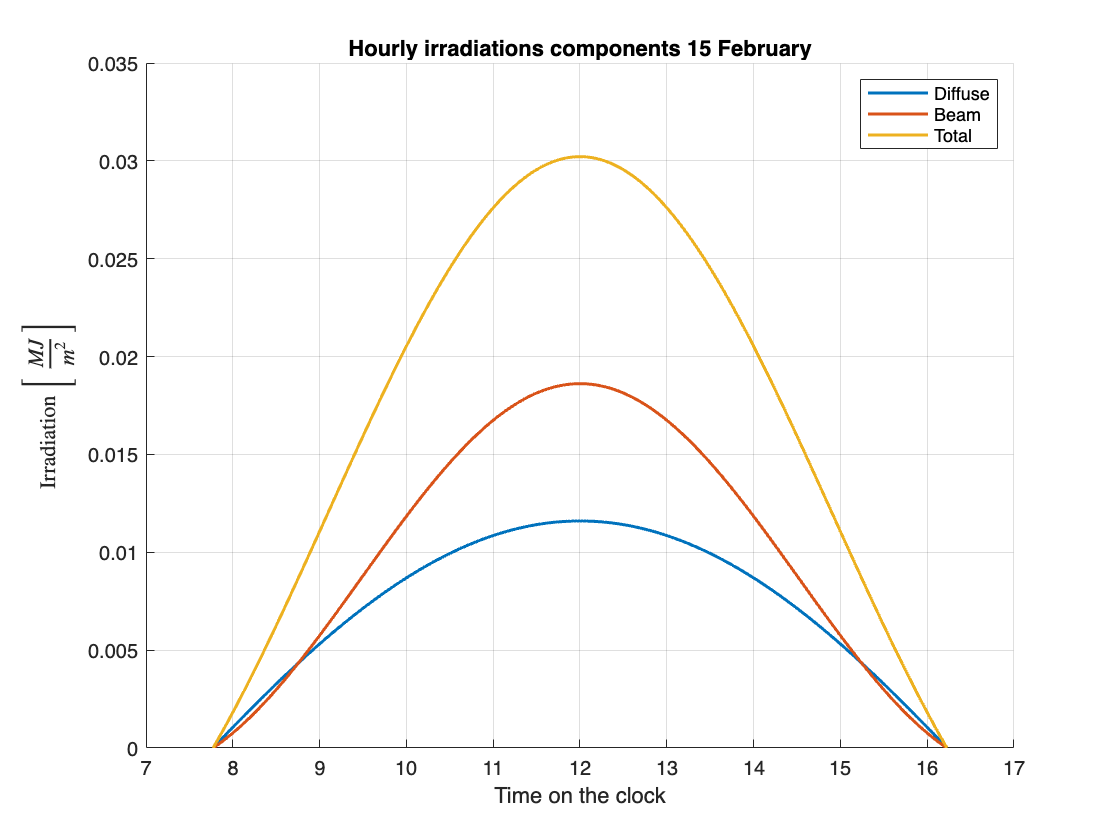

fig = fig+1;
figure(fig);
hold on; grid on;
plot(time, Dt_Table.Month{n}, 'LineWidth', 1.5);                     % Diffuse (using n = 2 since February is the sencond month)
plot(time, Bt_Table.Month{n}, 'LineWidth', 1.5);                     % Beam
plot(time, Ht_Table.Month{n}, 'LineWidth', 1.5);                     % Total
xlabel('Time on the clock')
ylabel('Irradiation $\left[\;\frac{MJ}{m^2}\;\right]$','Interpreter','latex');
legend('Diffuse','Beam','Total')
hold off;
title('Hourly irradiations components 15 February');

#### Incident Collector Radiation 

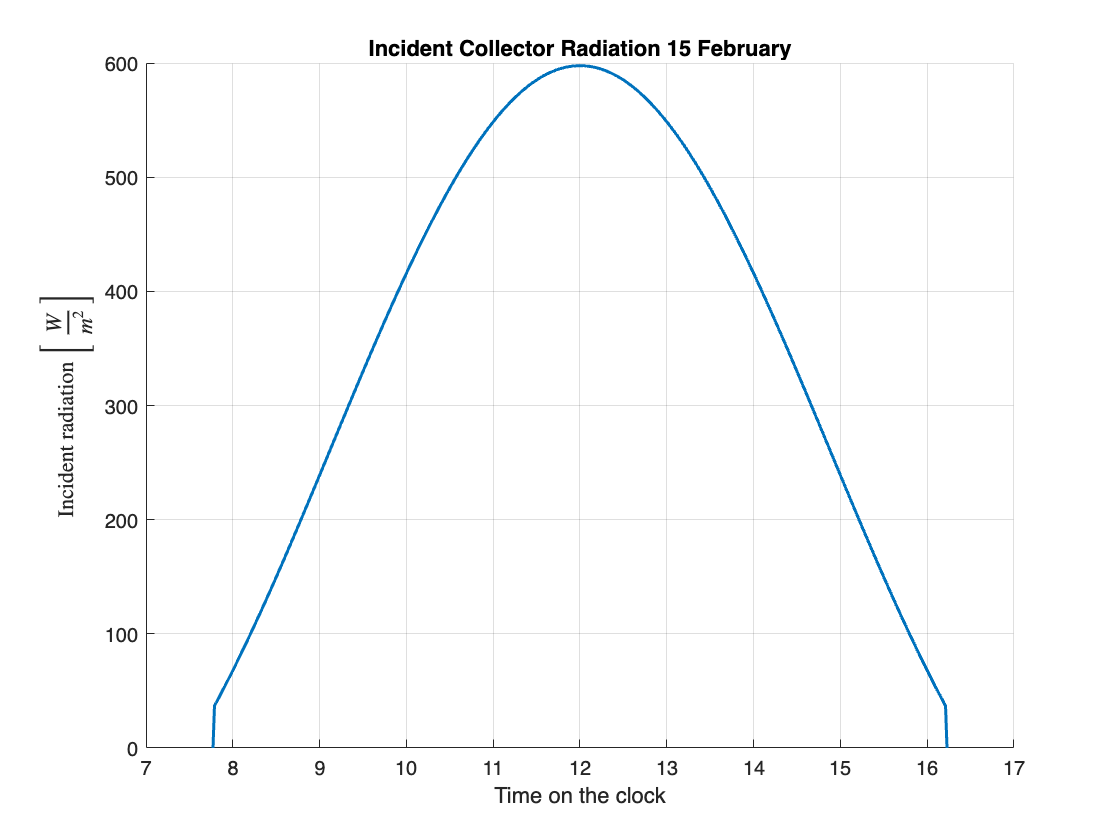

fig = fig+1;
figure(fig);
hold on; grid on;
plot(time, I_Table.Month{n}, 'LineWidth', 1.5);   % Using n = 2 since February is the sencond month
xlabel('Time on the clock')
ylabel('Incident radiation $\left[\;\frac{W}{m^2}\;\right]$','Interpreter','latex');
hold off;
title('Incident Collector Radiation 15 February');

#### Setting Simulation:

Expanding vectors on a minutes scale in order to compare results of simulation.

Irradiance:

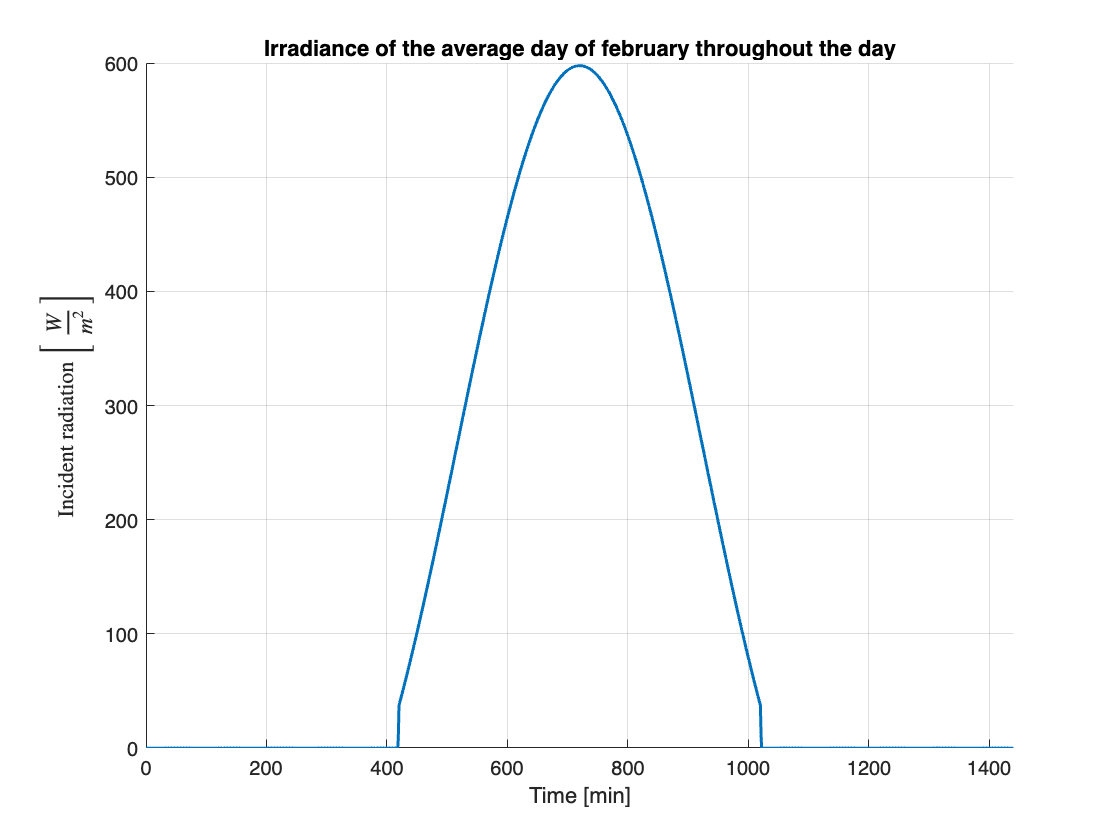

min = linspace(0, 1440, 1441)';            % Minutes in a day
min_daylight_500 = linspace(t_sr_Table.Month(n)*60, t_ss_Table.Month(n)*60, length(I_Table.Month{n})); % Vector with daylight (500 steps)

I_feb = interp1(min_daylight_500, I_Table.Month{n}, min, 'linear', 0);   % Interpolated values of I from t_sr-t_ss to the whole day in minutes                 
                                           
% PLOT
fig = fig+1;
figure(fig);
hold on; grid on;
plot(min, I_feb, 'LineWidth', 1.5);
xlim([0 1441]);
xlabel('Time [min]');
ylabel('Incident radiation $\left[\;\frac{W}{m^2}\;\right]$','Interpreter','latex');
title('Irradiance of the average day of february throughout the day');

Ambient temperature:

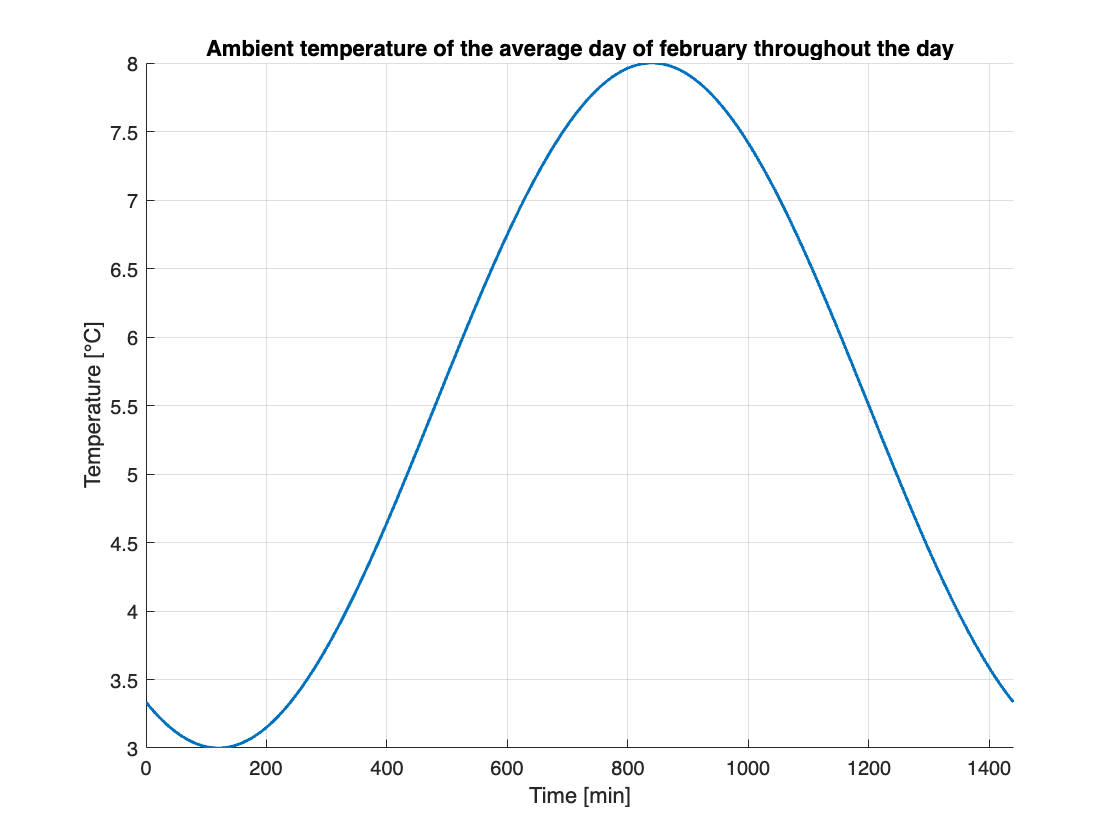

Ta_feb = (Tmax(n)+Tmin(n))/2 + (Tmax(n)-Tmin(n))/2*cos(2*pi/(24*60)*(min-tmax*60)); % Ambient temperature throughout the day in minutes
min_daylight = (t_sr_Table.Month(n)*60:t_ss_Table.Month(n)*60)';            % Vector containing minutes of daylight 
omega = pi/(12*60)*(min_daylight-12);                                       % Hour angle [rad/min] 
dt = 1;                                                                     % Temporal step of 1 minute 
% PLOT
fig = fig+1;
figure(fig);
hold on; grid on;
plot(min, Ta_feb, 'LineWidth', 1.5);
xlim([0 1441]);
xlabel('Time [min]');
ylabel('Temperature [°C]');
title('Ambient temperature of the average day of february throughout the day');

### 15 August

n = 8; % August is the 2-nd month

#### Hourly irradiations components

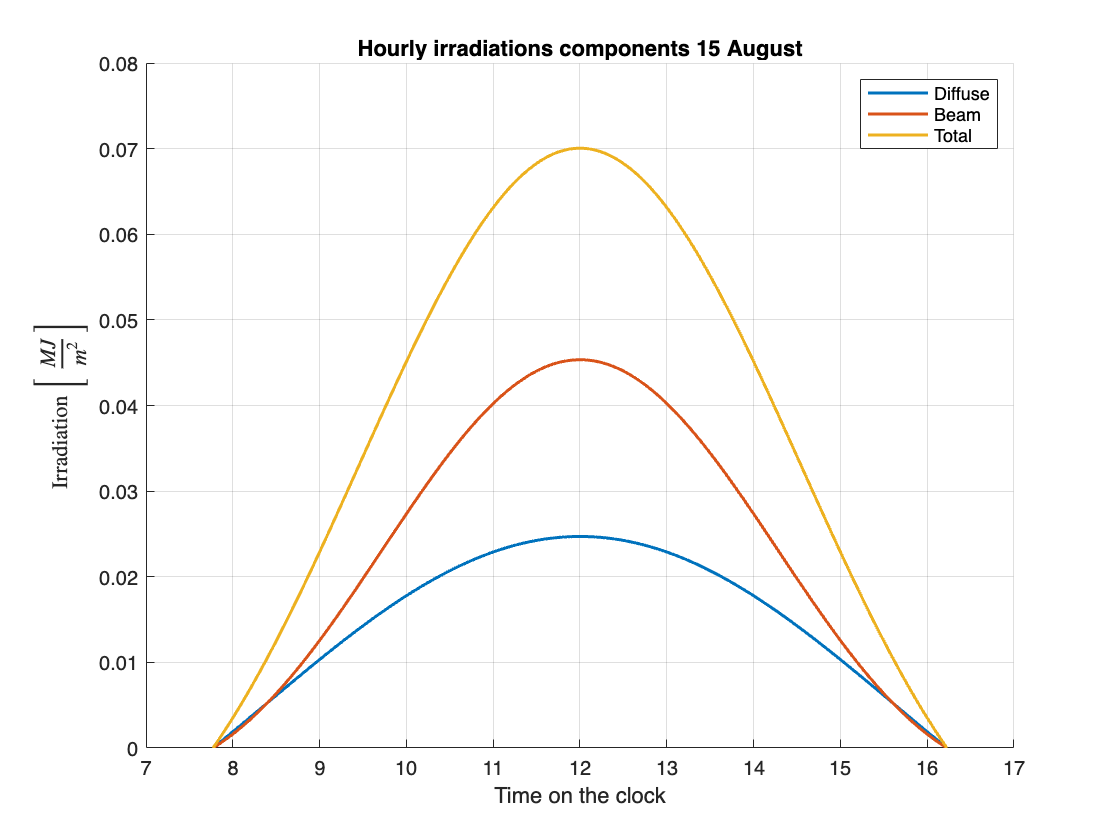

fig = fig+1;
figure(fig);
hold on; grid on;
plot(time, Dt_Table.Month{n}, 'LineWidth', 1.5);                     % Diffuse (using n = 8 since August is the eighth month)
plot(time, Bt_Table.Month{n}, 'LineWidth', 1.5);                     % Beam
plot(time, Ht_Table.Month{n}, 'LineWidth', 1.5);                     % Total
xlabel('Time on the clock')
ylabel('Irradiation $\left[\;\frac{MJ}{m^2}\;\right]$','Interpreter','latex');
legend('Diffuse','Beam','Total')
hold off;
title('Hourly irradiations components 15 August');

#### Incident Collector Radiation 

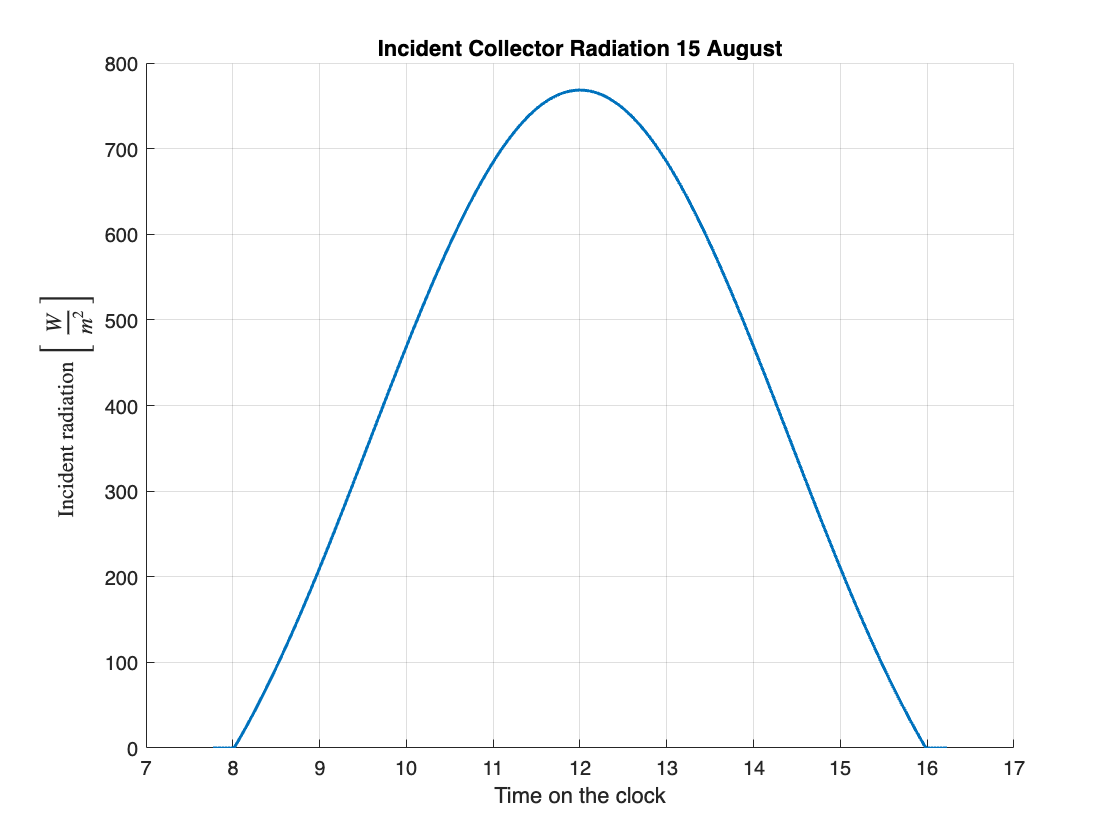

fig = fig+1;
figure(fig);
hold on; grid on;
plot(time, I_Table.Month{n}, 'LineWidth', 1.5);  % Using n = 8 since August is the sencond month
xlabel('Time on the clock')
ylabel('Incident radiation $\left[\;\frac{W}{m^2}\;\right]$','Interpreter','latex');
hold off;
title('Incident Collector Radiation 15 August');

#### Setting Simulation:

Expanding vectors on a minutes scale in order to compare results of simulation.

Irradiance:

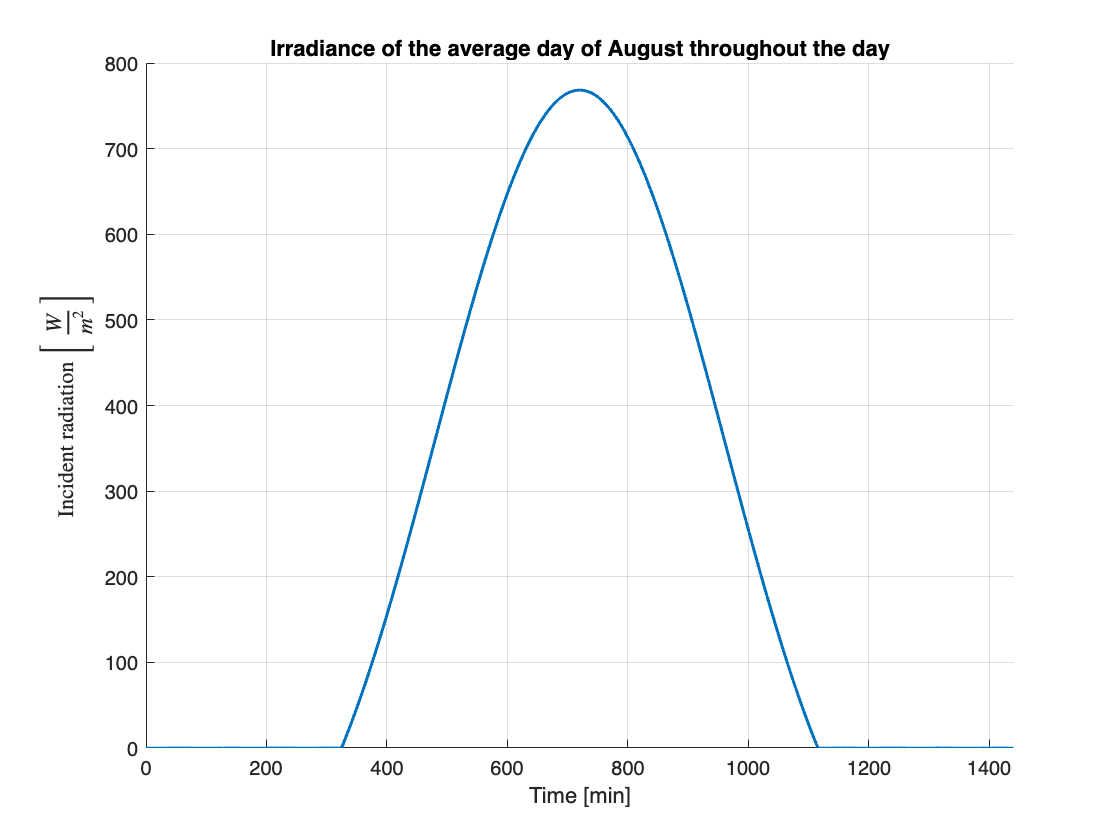

min = linspace(0, 1440, 1441)';            % Minutes in a day
min_daylight_500 = linspace(t_sr_Table.Month(n)*60, t_ss_Table.Month(n)*60, length(I_Table.Month{n})); % Vector with daylight (500 steps to match I_table)

I_feb = interp1(min_daylight_500, I_Table.Month{n}, min, 'linear', 0);   % Interpolated values of I from t_sr-t_ss to the whole day in minutes                 
                                           
% PLOT
fig = fig+1;
figure(fig);
hold on; grid on;
plot(min, I_feb, 'LineWidth', 1.5);
xlim([0 1441]);
xlabel('Time [min]');
ylabel('Incident radiation $\left[\;\frac{W}{m^2}\;\right]$','Interpreter','latex');
title('Irradiance of the average day of August throughout the day');

Ambient temperature:

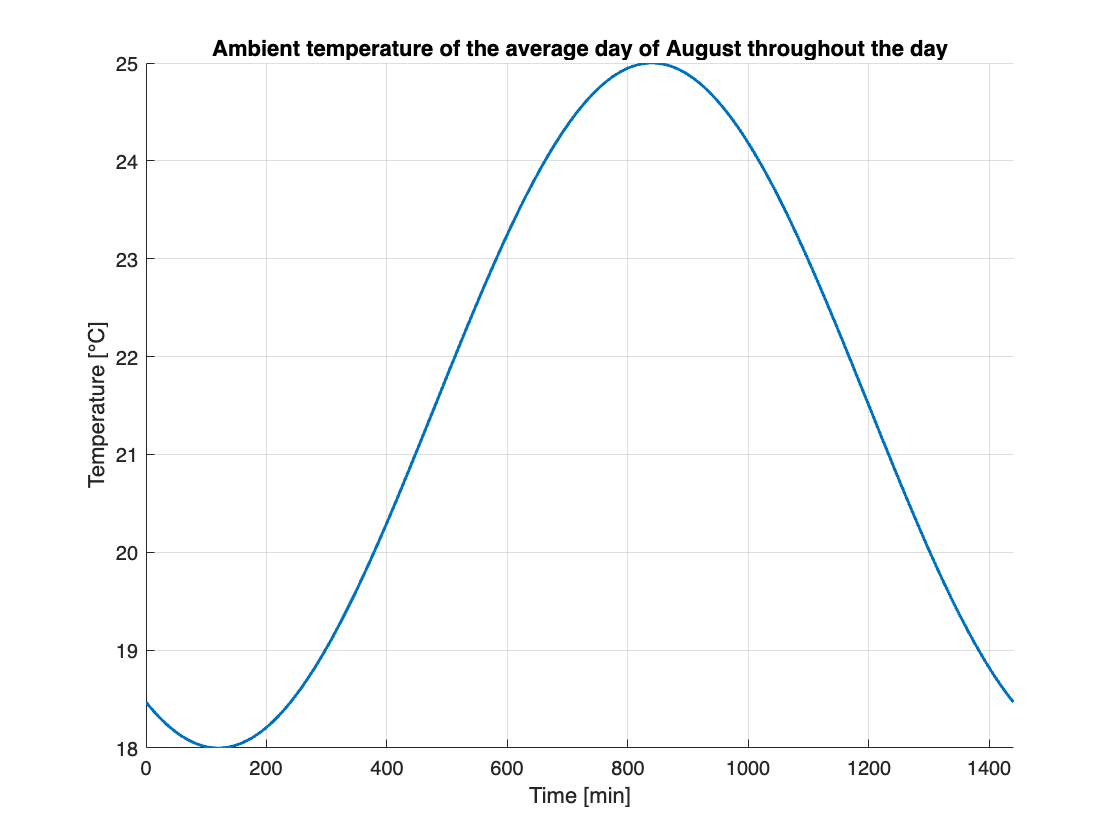

Ta_aug = (Tmax(n)+Tmin(n))/2 + (Tmax(n)-Tmin(n))/2*cos(2*pi/(24*60)*(min-tmax*60)); % Ambient temperature throughout the day in minutes
min_daylight = (t_sr_Table.Month(n)*60:t_ss_Table.Month(n)*60)';            % Vector containing minutes of daylight 
omega = pi/(12*60)*(min_daylight-12);                                       % Hour angle [rad/min] 
dt = 1;                                                                     % Temporal step of 1 minute 
% PLOT
fig = fig+1;
figure(fig);
hold on; grid on;
plot(min, Ta_aug, 'LineWidth', 1.5);
xlim([0 1441]);
xlabel('Time [min]');
ylabel('Temperature [°C]');
title('Ambient temperature of the average day of August throughout the day');

### Consumption Profiles

FR_consumption = 0*min;                   % Flow rate consumption [l/min]
TR_consumption = 0*min;                   % Temperature requested consumption [°C]
semester = 1;                              % 1 = summer, 2 = winter

if semester == 1                           % Summer

    T_mains = 16;

    FR_consumption(7*60:7*60+10) = 15;     % Morning shower: 10 [min] - 15 [l/min]
    TR_consumption(7*60:7*60+10) = 32;     % Morning shower: 10 [min] - 32 [°C]

    FR_consumption(7.5*60:7.5*60+4) = 6;   % Morning tooth brushing: 4 [min] - 6 [l/min]
    TR_consumption(7.5*60:7.5*60+4) = 27;  % Morning tooth brushing: 4 [min] - 27 [°C]

    FR_consumption(13*60:13*60+6) = 6;     % Lunch dishes washing: 6 [min] - 6 [l/min]
    TR_consumption(13*60:13*60+6) = 40;    % Lunch dishes washing: 6 [min] - 40 [°C]

    FR_consumption(15*60:15*60+3) = 4;     % After nap face washing: 3 [min] - 4 [l/min]
    TR_consumption(15*60:15*60+3) = 30;    % After nap face washing: 3 [min] - 30 [°C]

    FR_consumption(20.5*60:20.5*60+6) = 6; % Dinner dishes washing: 6 [min] - 6 [l/min]
    TR_consumption(20.5*60:20.5*60+6) = 40;% Dinner dishes washing: 6 [min] - 40 [°C]

    FR_consumption(22*60:22*60+15) = 15;   % Morning shower: 15 [min] - 15 [l/min]
    TR_consumption(22*60:22*60+15) = 34;   % Morning shower: 15 [min] - 34 [°C]


elseif semester == 2                       % Winter

    T_mains = 12;

    FR_consumption(6.5*60:6.5*60+12) = 15; % Morning shower: 12 [min] - 15 [l/min]
    TR_consumption(6.5*60:6.5*60+12) = 40; % Morning shower: 12 [min] - 40 [°C]

    FR_consumption(7*60:7*60+4) = 6;       % Morning tooth brushing: 4 [min] - 6 [l/min]
    TR_consumption(7*60:7*60+4) = 32;      % Morning tooth brushing: 4 [min] - 32 [°C]

    FR_consumption(12.7*60:12.7*60+6) = 6; % Lunch dishes washing: 6 [min] - 6 [l/min]
    TR_consumption(12.7*60:12.7*60+6) = 42;% Lunch dishes washing: 6 [min] - 42 [°C]

    FR_consumption(15*60:15*60+3) = 4;     % After nap face washing: 3 [min] - 4 [l/min]
    TR_consumption(15*60:15*60+3) = 38;    % After nap face washing: 3 [min] - 38 [°C]

    FR_consumption(19.5*60:19.5*60+6) = 6; % Dinner dishes washing: 6 [min] - 6 [l/min]
    TR_consumption(19.5*60:19.5*60+6) = 40;% Dinner dishes washing: 6 [min] - 40 [°C]

    FR_consumption(21*60:21*60+15) = 15;   % Morning shower: 15 [min] - 15 [l/min]
    TR_consumption(21*60:21*60+15) = 42;   % Morning shower: 15 [min] - 42 [°C]

else 
    
    error('Error: WRONG value of "semester". Check the value in the script.'); % Error for semester != 1||2

end

#### Visualization of Consumption requests:

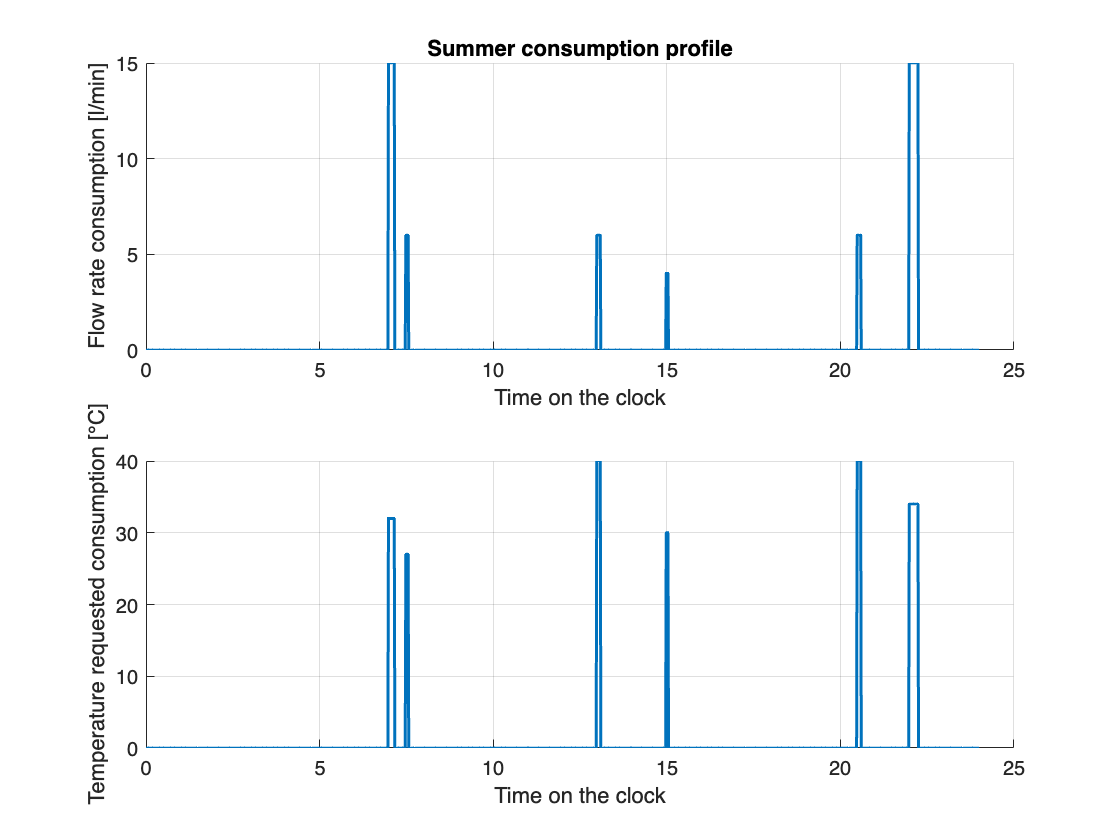

fig = fig+1;
figure(fig);
CP(1) = subplot(2,1,1);
hold on; grid on;
plot(min/60, FR_consumption,'LineWidth',1.5);
ylabel('Flow rate consumption [l/min]');
xlabel('Time on the clock');
if semester == 1
    title('Summer consumption profile');
elseif semester == 2
    title('Winter consumption profile');
else
    error('Error: WRONG value of "semester". Check the value in the script.'); % Error for semester != 1||2
end
CP(2) = subplot(2,1,2);
hold on; grid on;
plot(min/60, TR_consumption,'LineWidth',1.5);
ylabel('Temperature requested consumption [°C]');
xlabel('Time on the clock');

### SIMULATION OVER 2 DAYS